# Assignment 3 - Properties of the Hodgkin-Huxley equations

### 210218M Herath HMSI

hhconst;

## 1. Threshold

### Question 01

amp1 = 6; disp(amp1);

     6



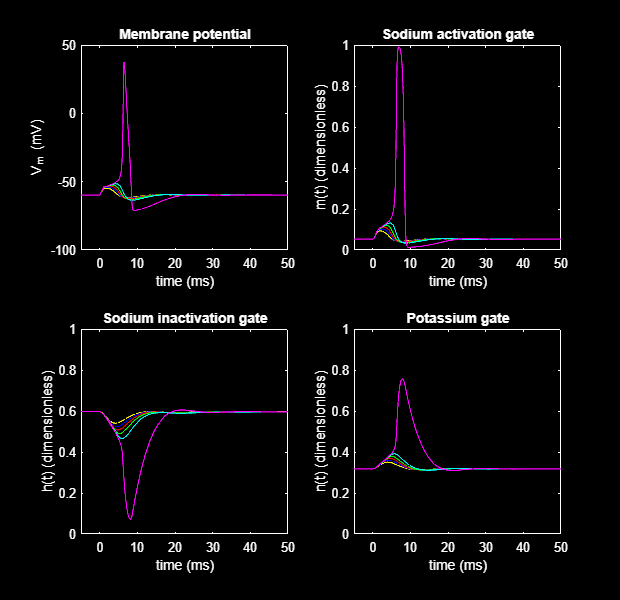

6.5000  
6.7500  
6.8750  
6.9375  
6.9688  


width1= 1;       %Sub-threshold current value
hhmplot(0,50,0);
% amp1 = 7;      %Supra-threshold current value
% hhmplot(0,50,1);

for n = 1:5
    amp1 = (amp1+7)/2;
    fprintf('%.4f  \n',amp1);
    hhmplot(0,50,1);
end

According to the 6 plots we can see that the amplitudes below including the 6.9375 does not pass the threshold value. Amplitudes above including 6.9688 have pass the threshold value. Therefore, the threshold value should be between 6.9375 - 6.9688. To obtain closest value we can try amplitudes between the received range.

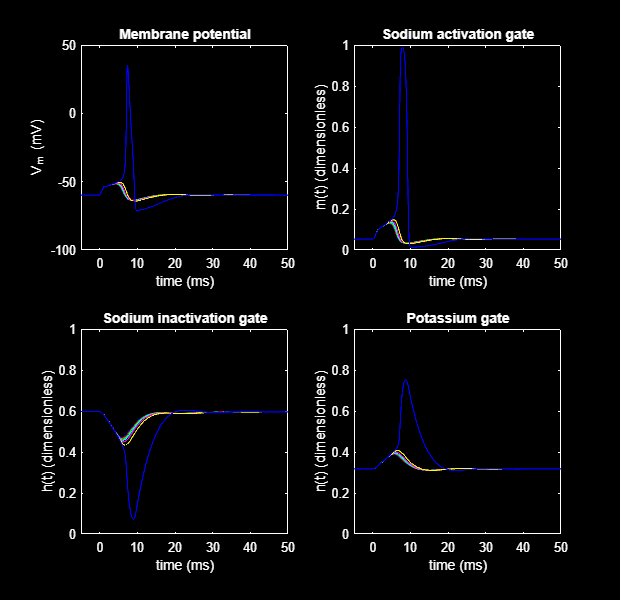

 6.9300 
 6.9350 
 6.9400 
 6.9450 
 6.9500 
 6.9550 
 6.9600 


tamp1 = 6.93; amp1 = tamp1; 
hhmplot(0,50,0); 

for n = 0:6
    amp1 = tamp1+0.005*n;    %To receive up to 2 decimal place accuracy we need to increment by 0.005
    outputString = sprintf(' %.4f \n',amp1); fprintf('%s',outputString);     %displaying the output
    hhmplot(0,50,1);
end

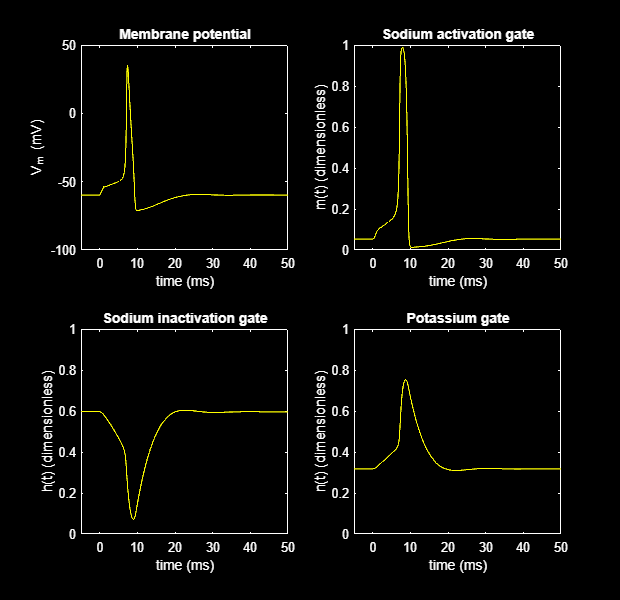

hhmplot(0,50,0);

At the last amplitude value threshold is reached and action potential has been elicited. But not in 6.9550 input. So according to the results we can clearly see the threshold value is about **6.96** $\textrm{µA}\;{\textrm{cm}}^{-2}$$ $

### Question 02

Let's find    for some different amplitudes .

amp1 = 6.9000

Jie_Integral = 6.9000

total_current_densities = 6.8998

amp1 = 6.9100

Jie_Integral = 6.9100

total_current_densities = 6.9100

amp1 = 6.9200

Jie_Integral = 6.9200

total_current_densities = 6.9199

amp1 = 6.9300

Jie_Integral = 6.9300

total_current_densities = 6.9300

amp1 = 6.9400

Jie_Integral = 6.9400

total_current_densities = 6.9399

amp1 = 6.9500

Jie_Integral = 6.9500

total_current_densities = 6.9500

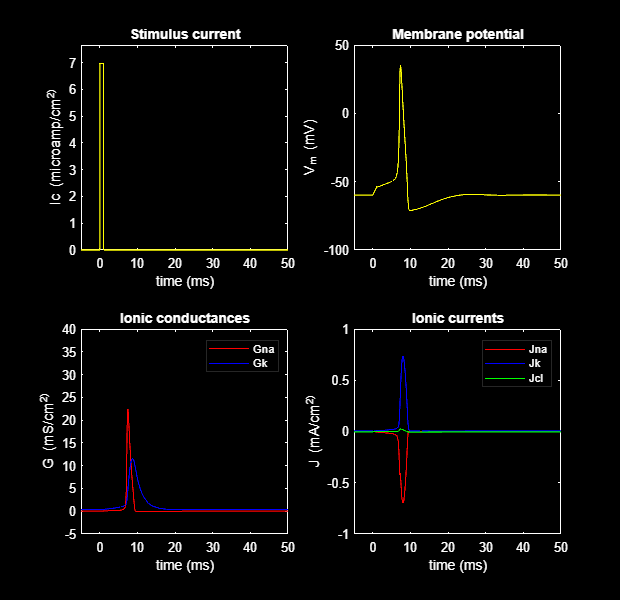

amp1 = 6.9600

Jie_Integral = 6.9600

total_current_densities = 6.9620

amp1 = 6.90;

for n=1:7
    [qna, qk, ql] = hhsplot(0,50);
    display(amp1);
    Jie_Integral = width1*amp1
    total_current_densities = qna+qk+ql
    fprintf('\n \n');
    amp1 = amp1+0.01;
end

The last plots are related to threshold  value of amp1.

By observing above values, we can say that 

##                          
$$\[\int_{t_0}^{t_f} \sum_k J_k\ dt  = \int_{t_0}^{t_f} \ J_{ie}\ dt \]$$


## 2. Refractoriness

### Question 03

amp1=26.8

Initialize a stimulus with amp1 = 26.8V and then introduce another pulse at amp2 = 13.4V(twice as the threshold) with same width. 

amp2=13.4   delay2 = 25

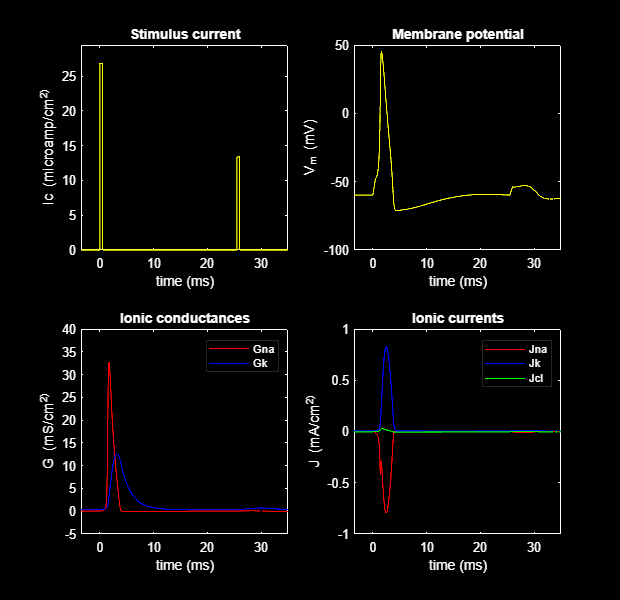

amp1 = 26.8;
width1 = 0.5;
delay2 = 25;

amp2 = 13.4;
width2 = 0.5;
hhsplot(0,35); 

Observation is, 13.4 μA${\textrm{cm}}^{-2}$ not enough to generate an action potential.

**delay2 = 13.7.**

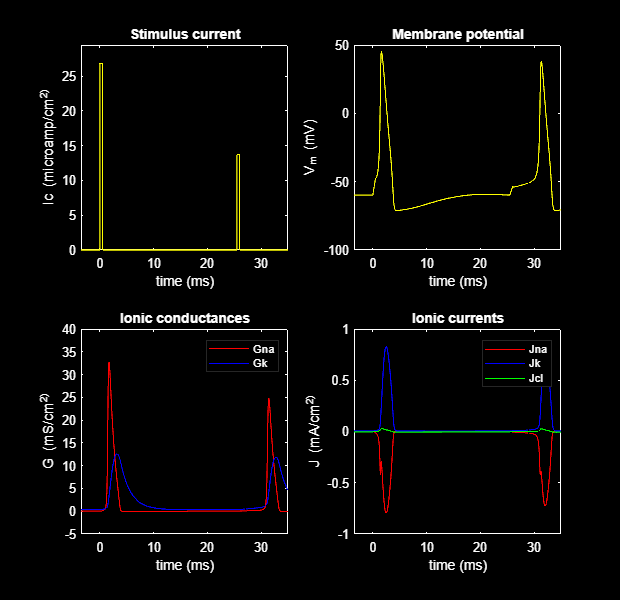

amp1 = 26.8;
width1 = 0.5;
delay2 = 25;

amp2 = 13.7;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **25 ms** delay is **13.7 **μA${\textrm{cm}}^{-2}$ .

**delay2 = 20**

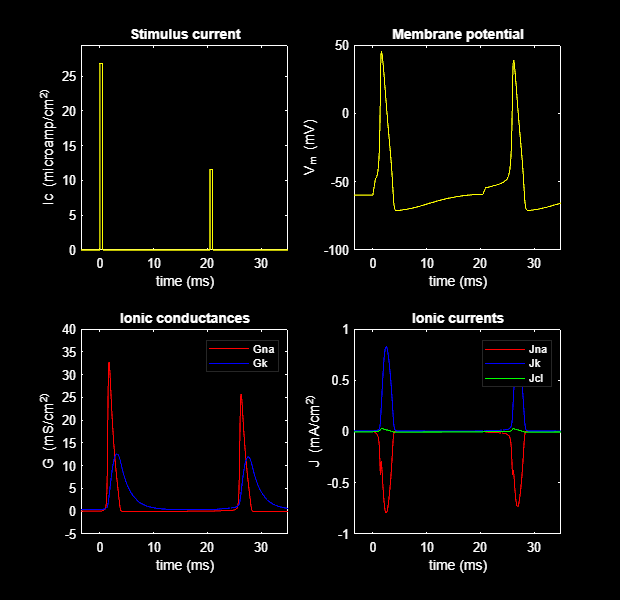

amp1 = 26.8;
width1 = 0.5;
delay2 = 20;

amp2 = 11.6;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **20 ms** delay is **11.6** μA${\textrm{cm}}^{-2}$** .**

**delay2 = 18**.

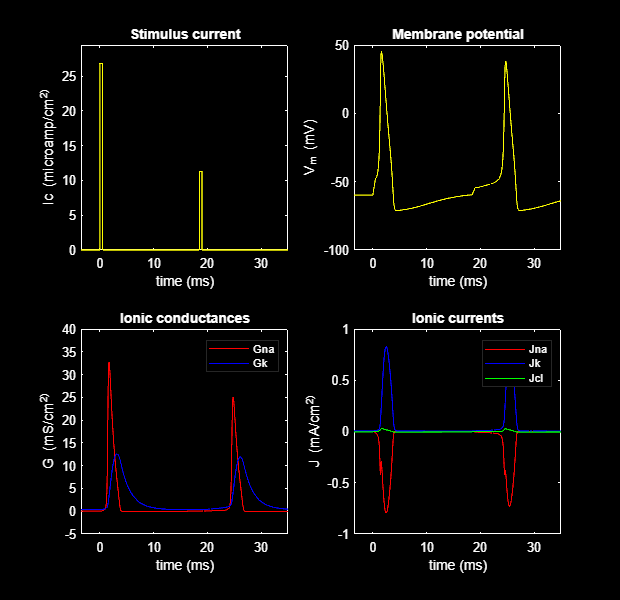

amp1 = 26.8;
width1 = 0.5;
delay2 = 18;

amp2 = 11.3;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **18 ms** delay is **11.3 **μA${\textrm{cm}}^{-2}$** .**

**delay2 = 16**.

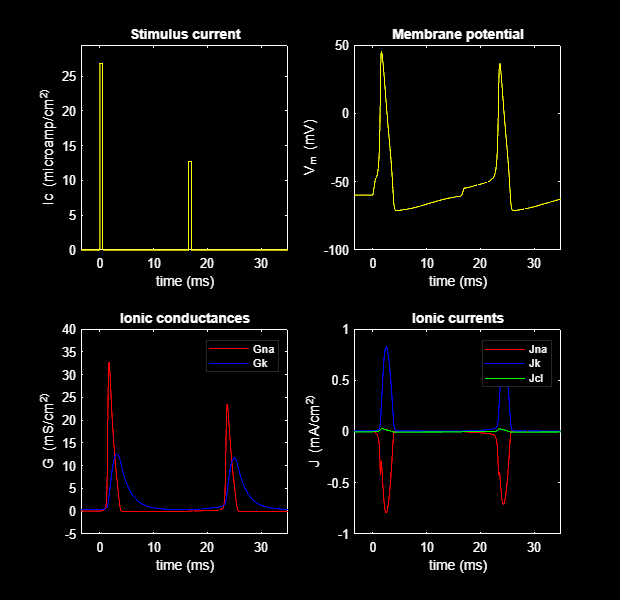

amp1 = 26.8;
width1 = 0.5;
delay2 = 16;

amp2 = 12.7;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **16 ms** delay is **12.7 **μA${\textrm{cm}}^{-2}$ 

**delay2 = 14**.

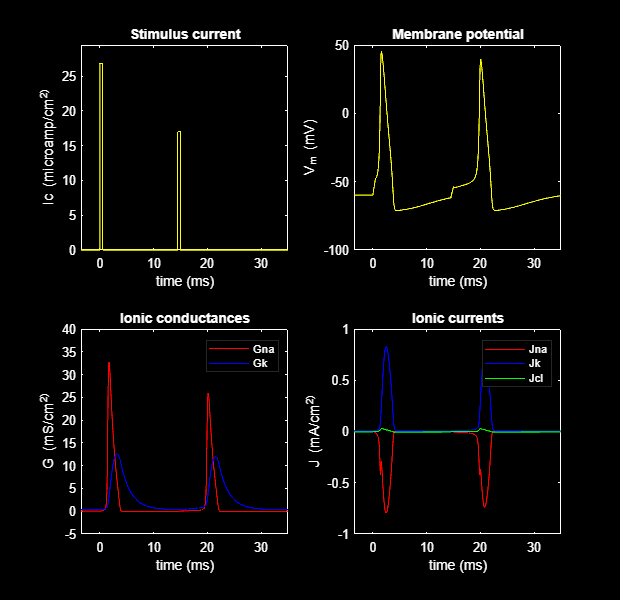

amp1 = 26.8;
width1 = 0.5;
delay2 = 14;

amp2 = 17.0;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **14 ms** delay is **17 **μA${\textrm{cm}}^{-2}$ 

**delay2 = 12**.

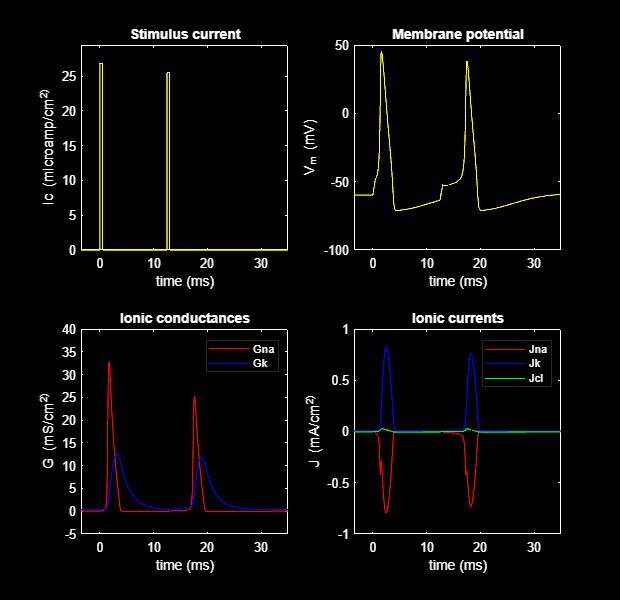

amp1 = 26.8;
width1 = 0.5;
delay2 = 12;

amp2 = 25.5;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **12 ms** delay is **25.5 **μA${\textrm{cm}}^{-2}$ 

**delay2 = 10**.

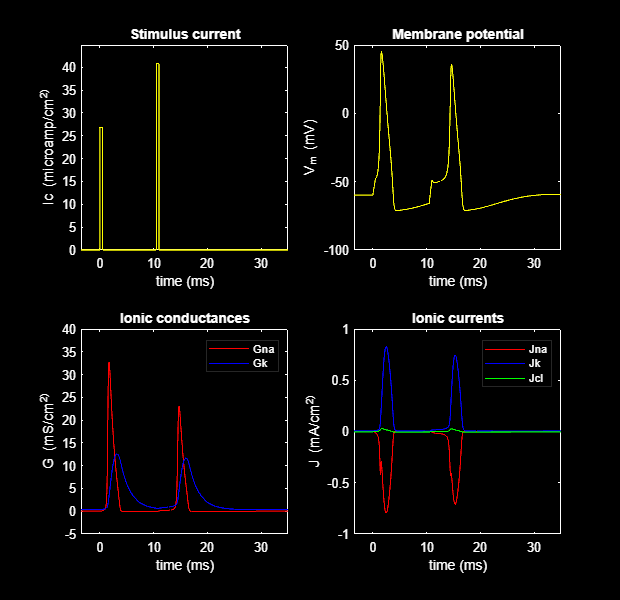

amp1 = 26.8;
width1 = 0.5;
delay2 = 10;

amp2 = 40.8;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **10 ms** delay is **40.8 **μA${\textrm{cm}}^{-2}$ 

**delay2 = 8**.

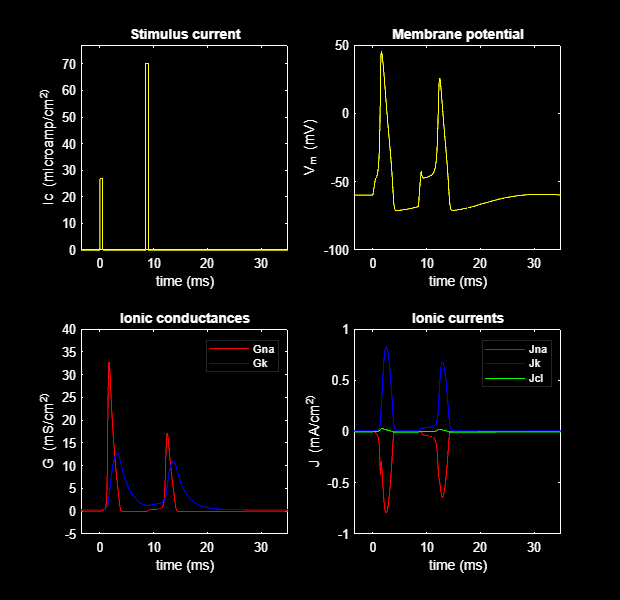

amp1 = 26.8;
width1 = 0.5;
delay2 = 8;

amp2 = 70.1;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **8 ms** delay is **70.1 **μA${\textrm{cm}}^{-2}$ 

**delay2 = 6**.

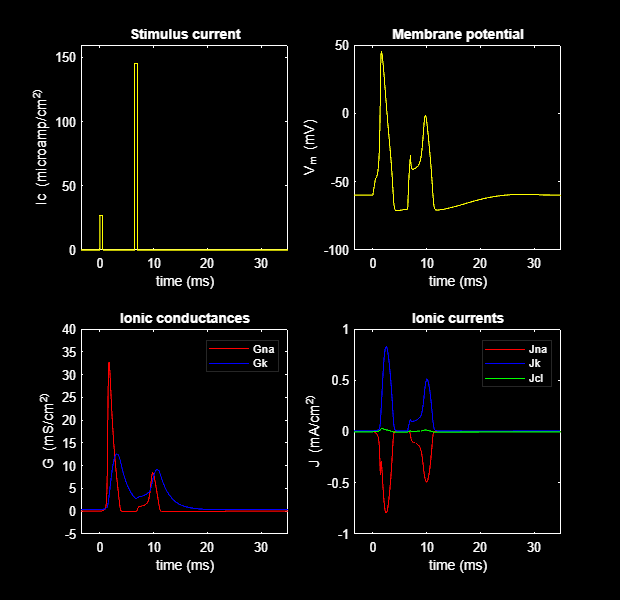

amp1 = 26.8;
width1 = 0.5;
delay2 = 6;

amp2 = 145.2;
width2 = 0.5;
hhsplot(0,35);

New threshold of amp2 for eliciting an action potential after **6 ms** delay is **145.2 **μA${\textrm{cm}}^{-2}$ (Output voltage is just above the 0V)

_

**Readings**

delay = [6; 8; 10; 12; 14; 16; 18; 20; 25];
Second_impulse = [145.2; 70.1; 40.8; 25.5; 17.0; 12.7; 11.3; 11.6; 13.7];
Table = table(delay,Second_impulse)

Table = 9×2 table
    delay    Second_impulse
    _____    ______________

      6          145.2     
      8           70.1     
     10           40.8     
     12           25.5     
     14             17     
     16           12.7     
     18           11.3     
     20           11.6     
     25           13.7     


### Question 04

The ratio  $\frac {I_{2th}}{I_{1th}}$ as a function of inter-pulse interval

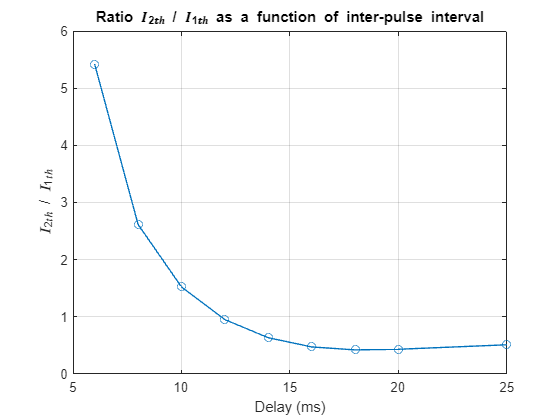

Delays = [6, 8, 10, 12, 14, 16, 18, 20, 25];
Current_ratio = [145.2, 70.1, 40.8, 25.5, 17.0, 12.7, 11.3, 11.6, 13.7]./26.8;
figure;
plot(Delays,Current_ratio,'o-');
title('Ratio 𝐼_{2𝑡ℎ} / 𝐼_{1𝑡ℎ} as a function of inter-pulse interval')
xlabel('Delay (ms)')
ylabel('𝐼_{2𝑡ℎ} / 𝐼_{1𝑡ℎ}')
grid on

We can see that when delay is about 6ms, the required current is about more than 5 times higher than initial threshold value. Therefore, 

**absolute refractory period is 0 - 6 ms**.

Also we can see, after 12ms, the required pulse is lower than the initinal threshold value. Therefor, we can say, The **r**

**elative refractory period is 6 - 12 ms.**

## **3. Repetitive activity**

### **Question 05**

- Amplitude = 5

No. of Action Potentials = 1

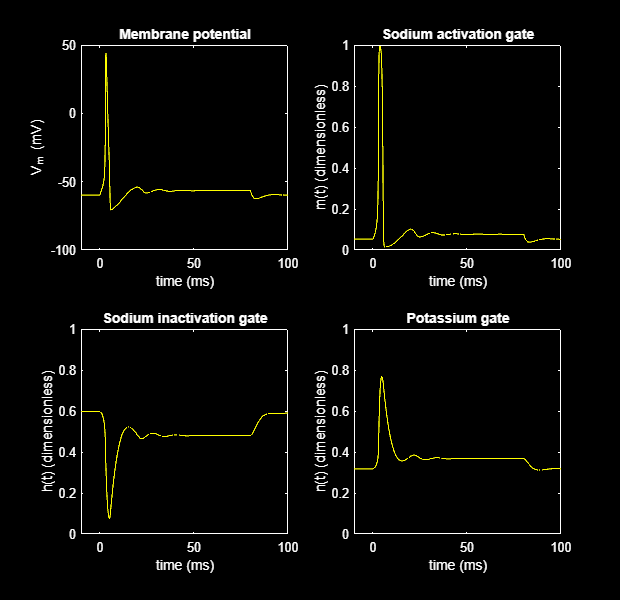

amp1 = 5;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 10

 No. of Action Potentials = 6

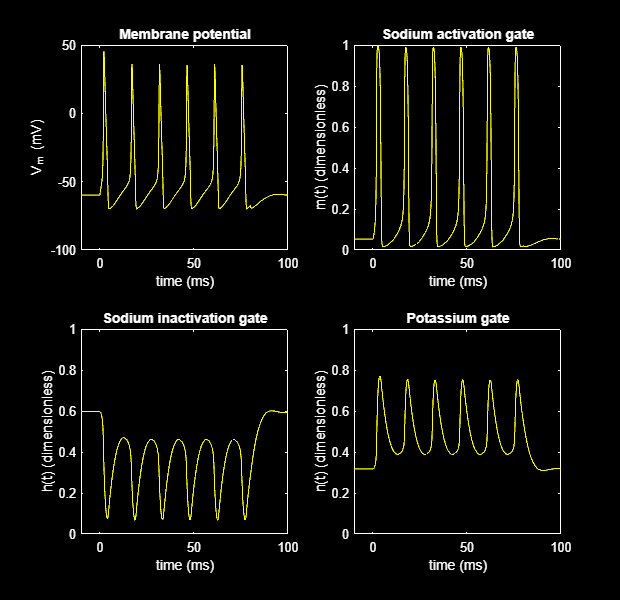

amp1 = 10;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 20

No. of Action Potentials = 7

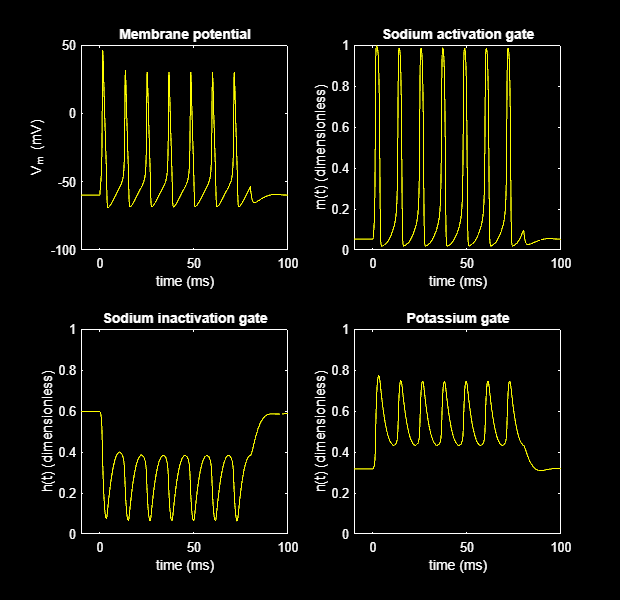

amp1=20;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 30

No. of Action Potentials = 8

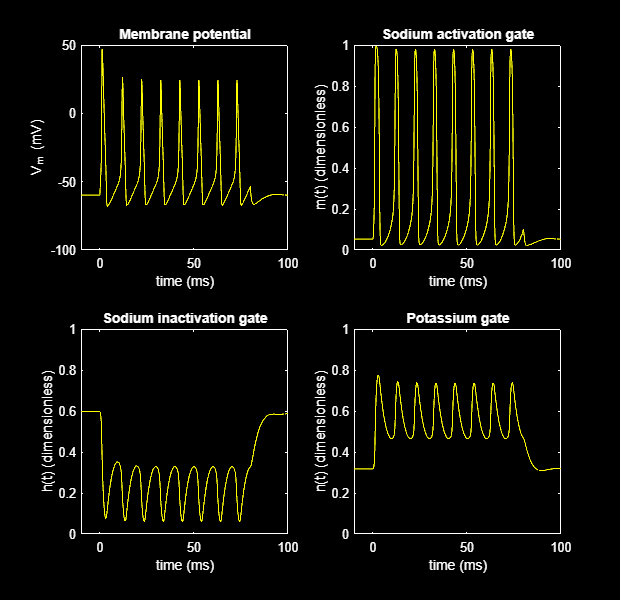

amp1=30;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 50

No. of Action Potentials = 10

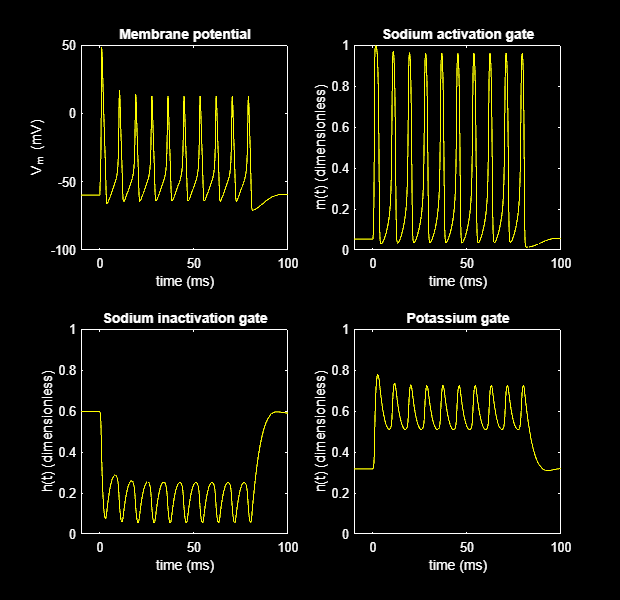

amp1=50;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 70

No. of Action Potentials = 11

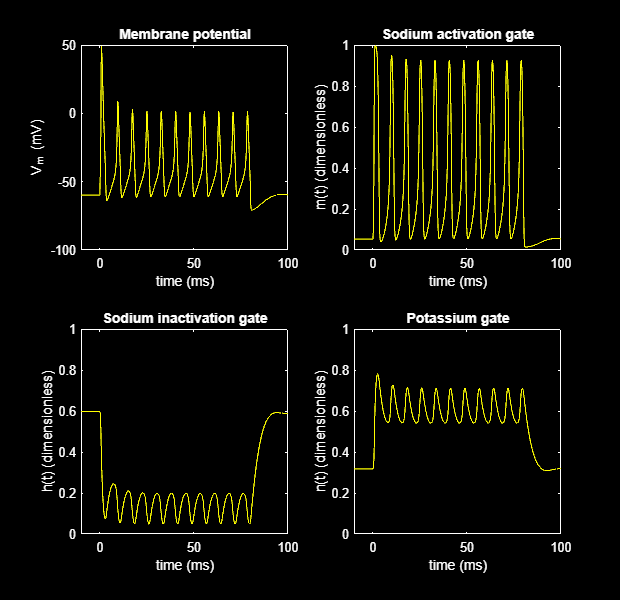

amp1=70;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

- Amplitude = 100

No. of Action Potentials = 12

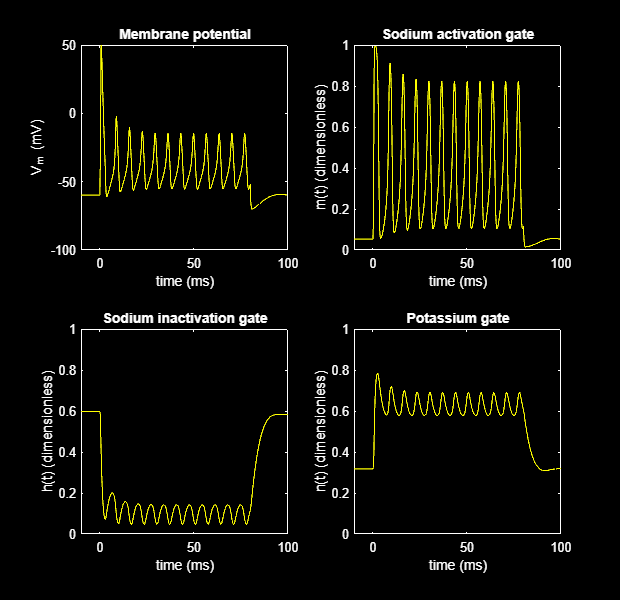

amp1=100;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

**Summary**

Amplitude = [5; 10; 20; 30; 50; 70; 100];
Number_of_Action_Potentials = [1; 6; 7; 8; 10; 11; 12];
Table = table(Amplitude,Number_of_Action_Potentials)

Table = 7×2 table
    Amplitude    Number_of_Action_Potentials
    _________    ___________________________

         5                    1             
        10                    6             
        20                    7             
        30                    8             
        50                   10             
        70                   11             
       100                   12             


**Action potential frequency as a function of stimulating current amplitude.**

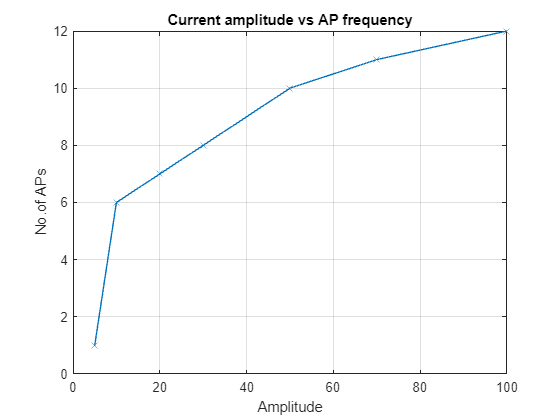

Amplitudes = [5, 10, 20, 30, 50, 70, 100];
No_of_Aps = [1, 6, 7, 8, 10, 11, 12];
figure;
plot(Amplitudes,No_of_Aps,'x-');
xlabel('Amplitude')
ylabel('No.of APs')
title('Current amplitude vs AP frequency')
grid on

By observing above graphs, we can say

- Amplitude of the first action potential is higher is all cases and it increases relatively with stimulus intensity amplitude.

- Amplitude of the action potentials except the first one decrease when stimulus intensity amplitude increase.

- Frequency of eliciting an action potential increases with stimulus intensity amplitude

### Question 06

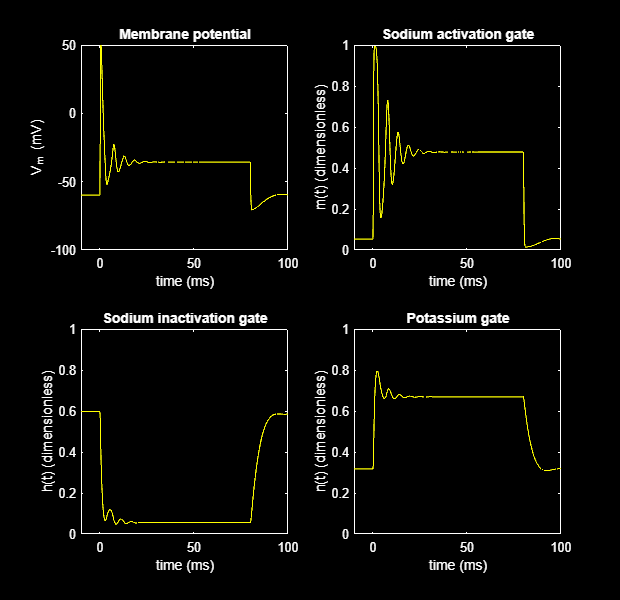

amp1=200;
width1 = 80;
delay2 = 0;

amp2 = 0;
width2 = 0;
hhmplot(0,100,0);

When the intensity of the electrical current is increased, an intriguing phenomenon takes place within the neuron. The cell membrane, which normally maintains a stable charge, becomes rapidly depolarized. This depolarization occurs due to the activation of specific voltage-gated sodium channels, denoted as the "m factor." As these channels open, sodium ions rush into the neuron, initiating a remarkable event known as an action potential.

However, the augmented depolarization also exerts an influence on another factor called the "h factor." This factor pertains to the inactivation of sodium channels. As the membrane potential reaches higher levels, the h factor becomes more prominent, causing the inactivation of a portion of the voltage-gated sodium channels. Consequently, fewer sodium channels are available to contribute to the rising phase of the action potential, resulting in a diminished amplitude.

Let us now consider the n factor in the Hodgkin-Huxley equations, which signifies the activation variable for potassium channels. These channels play a crucial role in repolarizing the neuron's membrane potential by allowing potassium ions to exit the cell. However, at extremely high levels of depolarization, the n factor undergoes a significant decrease, causing a decline in the activation of potassium channels. This, in turn, hampers the repolarization process, as the potassium channels remain inactivated and the membrane voltage persists in a depolarized state.

## 4. Temperature dependence

### Question 07

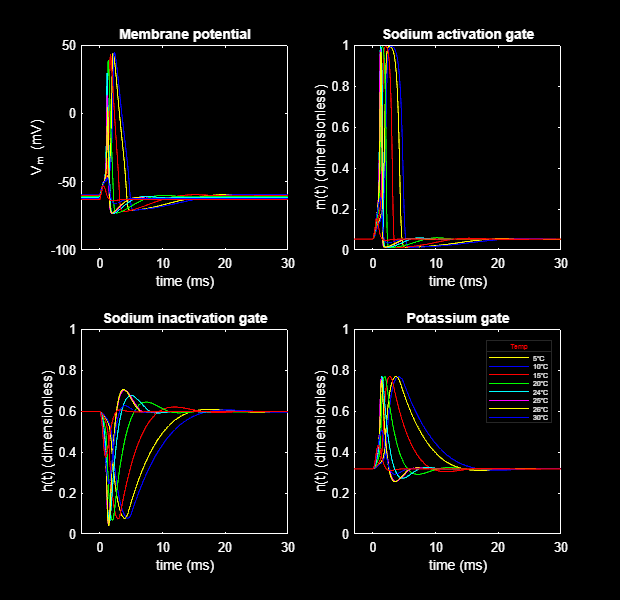

% Initialize variables
vclamp = 0;
amp1 = 20;
width1 = 0.5;


% Define the temperatures and labels
temperatures = [5, 10, 15, 20, 24, 25, 26, 30];
labels = arrayfun(@(temp) sprintf('%d°C', temp), temperatures, 'UniformOutput', false);

hhmplot(0, 30, 0);
tempc = 0;
% Loop through each temperature and plot
for i = 1:length(temperatures)
    tempc = temperatures(i);
    hhmplot(0, 30, i);
end

% Add legend
l = legend(labels, 'Location', 'northeast');
l.Title.String = 'Temp';

% Change legend font color and size
l.TextColor = 'white'; 
l.Title.Color = 'red'; 
l.FontSize = 5;

Each plot corresponding to a different temperature ranging from 0$C^0$ to 30$C^0$

Features the of action potential which are affected by incresing the temperature.

- **Amplitude:** Action potential amplitude decreases. As the delay in opening of K+ channels decreased. This cause to decrease the voltage rise due to Na+ influx.

- **Duration:** Time duration of the action potential decreases when the temperature increases.This is due to quicker depolariation and repolarization of Na+ and K+ channels with increased temperature.

- **Refractory Periods:** Both the absolute and relative refractory periods are shortened at higher temperatures. This is a consequence of the faster kinetics of ion channel inactivation and recovery processes.

- **Threshold:** The threshold potential for initiating an action potential generally becomes lower with increasing temperature. This is because the kinetics of ion channels (especially sodium channels) become faster, making it easier to reach the threshold.